# Vehicles - Object Detection with YOLO v2

You Only Look Once (YOLO) v2 is a deep neural network used for object detection. In this example, we will apply transfer learning to the ResNet-50 pretrained model to create a YOLO v2 detector.  

This is one of many object detection techniques in deep learning. For more information, see [object detection using deep learning](https://www.mathworks.com/help/vision/object-detection.html).

## View Dataset and Load Ground Truth

This example uses a vehicle dataset that has 295 images. Along with these images is a MAT file that provides ground truth data about the positions of 1-2 vehicles in each image.

data = load('vehicleDatasetGroundTruth.mat');
vehicleDataset = data.vehicleDataset;

% Display first few rows of the data set.
vehicleDataset(1:4,:)
% Add the fullpath to the local vehicle data folder.
vehicleDataset.imageFilename = fullfile('5-ObjectDetection','5-AdditionalFiles',vehicleDataset.imageFilename);

% View a random image 

ans = 4×2 table
              imageFilename                   vehicle     
    _________________________________    _________________

    {'vehicleImages/image_00001.jpg'}    {[220 136 35 28]}
    {'vehicleImages/image_00002.jpg'}    {[175 126 61 45]}
    {'vehicleImages/image_00003.jpg'}    {[108 120 45 33]}
    {'vehicleImages/image_00004.jpg'}    {[124 112 38 36]}


r = randi(295);

img = imread(vehicleDataset.imageFilename{r});
imgAnnotated = insertShape(img,'Rectangle',vehicleDataset.vehicle{r});
imgAnnotated = imresize(imgAnnotated,2);

imshow(imgAnnotated)
title(['Image ' num2str(r) ' with Bounding Box'])

## Split Dataset Into Training, Validation, and Test.

- 60% Training

- 10% Validation

- 30% Test

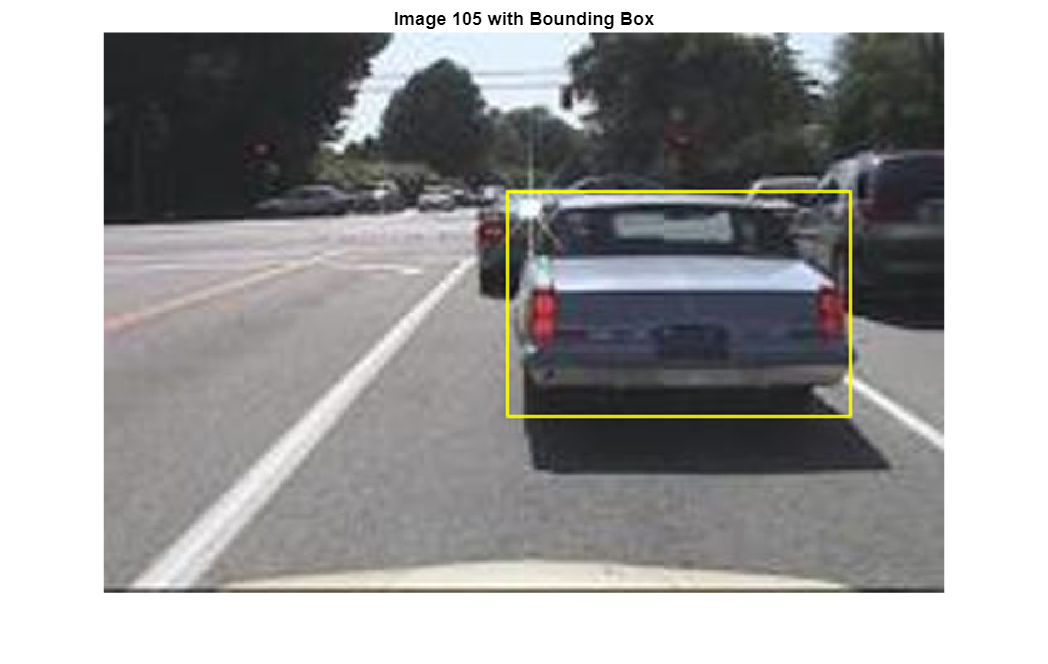

rng(0);
shuffledIndices = randperm(height(vehicleDataset));
idx = floor(0.6 * length(shuffledIndices) );


trainingIdx = 1:idx;
trainingDataTbl = vehicleDataset(shuffledIndices(trainingIdx),:);

validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = vehicleDataset(shuffledIndices(validationIdx),:);

testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = vehicleDataset(shuffledIndices(testIdx),:);

## Create Datastores for Images and Bounding Boxes

Use [`imageDatastore`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) and [`boxLabelDatastore`](https://www.mathworks.com/help/vision/ref/boxlabeldatastore.html) to create datastores for loading the image and label data during training and evaluation.

imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,'vehicle'));

imdsValidation = imageDatastore(validationDataTbl{:,'imageFilename'});
bldsValidation = boxLabelDatastore(validationDataTbl(:,'vehicle'));

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,'vehicle'));

Use [`combine`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.combine.html) to combine corresponding data from our image and box label datastores.

trainingData = combine(imdsTrain,bldsTrain);

% ADD CODE BELOW

% Fill in the arguments combining datastores for validation and test:
validationData = combine();
testData = combine();

## Create a YOLO v2 Object Detection Network

A YOLO v2 object detection network is composed of two subnetworks. 

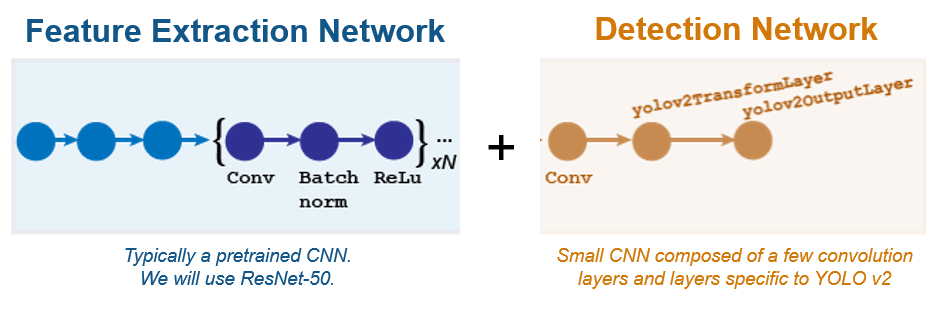

We will use the [`yolov2Layers`](https://www.mathworks.com/help/vision/ref/yolov2layers.html) function to create our YOLO v2 network. This function requires the following inputs, which we will define in our next block of code:

- Input size for ResNet-50 (224x224x3)

- Specify the names of object classes to detect ("vehicle")

- Anchor boxes - these are the detection boxes used by our network. We estimate their size based on the size of the objects in our training data ([Resource: Anchor Boxes for Object Detection](https://www.mathworks.com/help/vision/ug/anchor-boxes-for-object-detection.html))

- baseNet - Feature extraction network

- detectionSource - layer where we want to append the detection network.

**Specify Input arguments**

inputSize = [224 224 3];
classes = "vehicle";

Note that the training images used in this example vary in size and are bigger than the network input size, 224-by-224. To correct this, resize the images in a preprocessing step prior to training.

% Estimate size of anchor boxes based on the resized image data
trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));
numAnchors = 7;
[anchorBoxes,meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors)
baseNet = imagePretrainedNetwork("resnet50");
detectionSource = "activation_40_relu";

**Create YOLO v2 network**

detector = yolov2ObjectDetector(baseNet,classes,anchorBoxes,DetectionNetworkSource=detectionSource);

## Data Augmentation

Data augmentation is used to improve network accuracy by randomly transforming the original data during training. By using data augmentation you can add more variety to the training data without actually having to increase the number of labeled training samples.

Use [`transform`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.transform.html) to augment the training data by randomly flipping the image and associated box labels horizontally. 

augmentedTrainingData = transform(trainingData,@augmentData);

% Visualize the augmented images.
augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1},"rectangle",data{2});
    reset(augmentedTrainingData);
end
figure
montage(augmentedData,BorderSize=10)

## Preprocess Training and Validation Data

Preprocess the augmented training data, and the validation data to prepare for training.

preprocessedTrainingData = transform(augmentedTrainingData,@(data)preprocessData(data,inputSize));
preprocessedValidationData = transform(validationData,@(data)preprocessData(data,inputSize));

Read the preprocessed training data.

data = read(preprocessedTrainingData);

Display the image and bounding boxes.

I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,"rectangle",bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

## Train YOLO v2 Object Detector

Use `trainingOptions` to specify network training options. Set `'ValidationData'` to the preprocessed validation data. Set `'CheckpointPath'` to a temporary location. This enables the saving of partially trained detectors during the training process. If training is interrupted, such as by a power outage or system failure, you can resume training from the saved checkpoint.

**To do: Add in the following training options**

- `MiniBatchSize     16`

- `InitialLearnRate  1e-3`

- `MaxEpochs         10`

% miniBatchSize = 
% initalLearnRate = 
% maxEpochs = 

options = trainingOptions('adam', ...
        'ValidationData',preprocessedValidationData, ...
        'MiniBatchSize', miniBatchSize, ...
        'InitialLearnRate', initialLearnRate, ...
        'MaxEpochs', maxEpochs, ...
        'VerboseFrequency', 20);


Use [`trainYOLOv2ObjectDetector`](docid:vision_ref#mw_0ff9d26a-9a79-4333-a1b1-ba03c8539ee3) function to train YOLO v2 object detector if `doTraining` is true. Otherwise, load the pretrained network.

doTraining = false;
    
if doTraining       
     [detector,info] = trainYOLOv2ObjectDetector(preprocessedTrainingData,detector,options);
else
    pretrained = load("yolov2ResNet50VehicleExample_19b.mat");
    detector = pretrained.detector;
end

## Evaluate Detector Using Test Set

For this example, use the average precision metric to evaluate performance. The average precision provides a single number that incorporates the ability of the detector to make correct classifications (precision) and the ability of the detector to find all relevant objects (recall).

Apply the same preprocessing transform to the test data as for the training data. Note that data augmentation is not applied to the test data. Test data should be representative of the original data and be left unmodified for unbiased evaluation.

preprocessedTestData = transform(testData,@(data)preprocessData(data,inputSize));

Run the detector on all the test images.

detectionResults = detect(detector, preprocessedTestData);

Evaluate the object detector on the test data set.

metrics = evaluateObjectDetection(detectionResults,preprocessedTestData);

Compute the average precision (AP) metric and the precision/recall (PR) curve. The precision/recall curve highlights how precise a detector is at varying levels of recall. The ideal precision is 1 at all recall levels. The use of more data can help improve the average precision but might require more training time.

AP = averagePrecision(metrics,ClassName="vehicle");
[precision, recall] = precisionRecall(metrics,ClassName="vehicle");

## Precision/Recall Curve

These two metrics can be plotted on a curve to give us a sense of our detector's accuracy. Each metric produces a value between 0 and 1. 


$$\textrm{Precision}=\;\;\frac{\textrm{True}\;\textrm{Positives}}{\textrm{True}\;\textrm{Positives}+\textrm{False}\;\textrm{Positives}}$$



$$\textrm{Recall}\;=\;\;\frac{\textrm{True}\;\textrm{Positives}}{\textrm{True}\;\textrm{Positives}+\textrm{False}\;\textrm{Negatives}}$$


- True positive - object is correctly labeled as vehicle

- False positive - non-vehicle object is labeled as vehicle

- False negative - vehicle exists in the image but it is not labeled by detector

A perfect detector will have a precision level of 1 across all recall levels. We can plot a curve to see the relationship between these two metrics.

figure
plot(recall{:},precision{:})
xlabel("Recall")
ylabel("Precision")
grid on
title("Average Precision = "+AP)

## Summary

- Created YOLO v2 object detection network to detect vehicles

- Used data augmentation to increase amount of training data

- Evaluated network with precision/recall curve

*Copyright 2024 The MathWorks, Inc.*